240032 ExFinal Q1 2022-23 Problema 2

## Problem 2

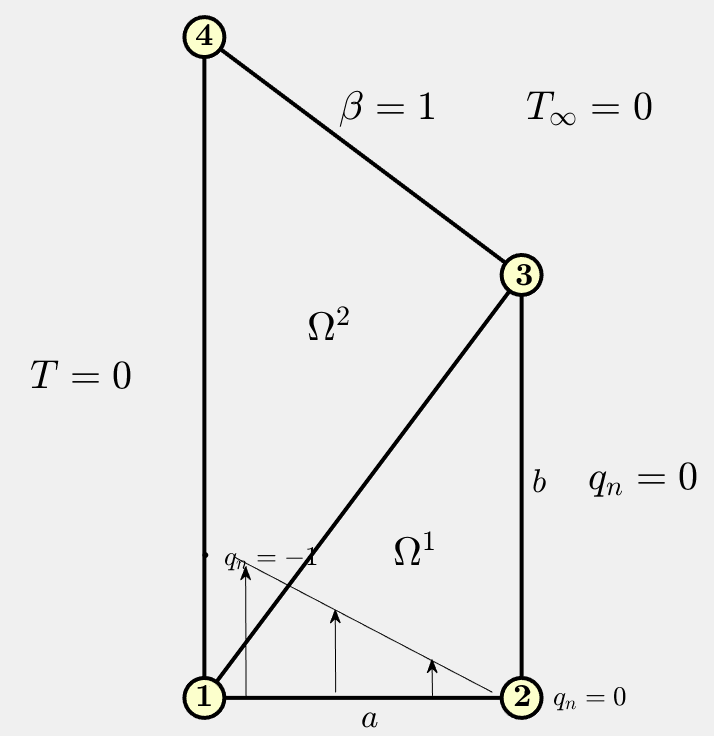

Consider the Poisson heat diffusion on the domain shown in the figure meshed by  two rectangular triangular finite elements with the local and global  numbering plotted there. We consider that the thermal conductivity is $k_{c} = 1$ and there is not internal heating ($f=0$). Also the temperature is $T=0$ on all the vertical left boundary, a linear negative flow $q_{n}$ on the edge between nodes $1$ and $2$ is applied with $q_{n} = -1$ and $q_{n} = 0$ respectively, the domain is isolated ($q_{n} = 0$) on the edge between nodes $2$ and $3$, while a convection of coefficient $\beta = 1$ and bulk temperature $T_{\infty} = 0$ is present at the edge between nodes $3$ and $4$. Let $a=3$, $b=4$ the lengths of the edges shown in the picture. Then as we suppose that $\Omega^{2}$ is also a rectangular triangle, all the other lengths of the other edges are already determined. 

clearvars
close all

a = 3.0;
b = 4.0;

kc = 1.0;           %Thermal conductivity 

% Linear flow on the edge L_{1,2}, with
q1 = -1.0;          %at node 1         
q2 = 0.0;           %at node 2

beta = 1;           %Coefficient for the convection on the edge L_{3,4}

### Questions

(a) (1 point)  So, the length of the edge between nodes $3$ and $4$ and is.

**Solution.  **First, we recall the usual notation following notation for edges' length: $h^{e}_{k}$ denotes the length of the edge $k$ of the element $\Omega^{e}$. As de domain is meshed by triangles $k=1,2,3$, being 

- Edge $k=1$, the edge joining the local element's nodes $1$ and $2$, $\Gamma^{e}_{1}$, i.e., $h^{e}_{1}= \ell(\Gamma^{e}_{1})$.

- Edge $k=2$, the edge joining the local element's nodes $2$ and $3$, $\Gamma^{e}_{2}$, i.e., $h^{e}_{2} =\ell(\Gamma^{e}_{2})$, and

- Edge $k=3$, the edge joining the local element's nodes $3$ and $1$. $\Gamma^{e}_{3}$, i.e., $h^{e}_{3} = \ell(\Gamma^{e}_{3})$.

Thus, according to the data: $h^{1}_{1} = a$, $h^{1}_{2} = b$, so $h^{2}_{1} = h^{1}_{3} = \sqrt{a^{2} + b^{2}$ and, with a bit of trigonometry, 


$$h^{2}_{2} = \frac{a}{b} h^{2}_{1} = \frac{a}{b}\sqrt{a^{2} + b^{2}}$$


(which is the length of the edge joining nodes $3$ and $4$), and


$$h^{2}_{3} = \sqrt{\left(h^{2}_{1}\right)^{2} + \left(h^{2}_{2}\right)^{2}} = \sqrt{a^{2} + b^{2} + \left(\frac{a}{b}^{2}\right)\left(a^{2} + b^{2}\right)} = \sqrt{\left(1 + \frac{a^{2}}{b^{2}}\right)\left(a^{2} + b^{2}\right)} =\frac{a^{2} + b^{2}}{b}$$


(which is the length joining nodes $4$ and $1$).

h = zeros(2,3); %1st index (row): element's number
                %2nd index (colum): edge's number
h(1,1) = a;
h(1,2) = b;
h(1,3) = sqrt(a^2 + b^2);
h(2,1) = h(1,3);
h(2,2) = a*h(1,3)/b;
h(2,3) = sqrt(h(2,1)^2 + h(2,2)^2);
fprintf(['*** So, the lenght of the edge joining nodes 3 and 4 is: %.4e\n',...
    '*** Hint. The length of the edge joining nodes 4 and 1 is: %.4e\n'],...
    h(2,2),h(2,3))

*** So, the lenght of the edge joining nodes 3 and 4 is: 3.7500e+00
*** Hint. The length of the edge joining nodes 4 and 1 is: 6.2500e+00


(b) (1 point) The entry of the local stiff matrix $K^{1}_{2,3}$ of is.

**Solution. **Using the formulas for the local stiff matrix when the element is a right triangle and$a_{11} = a_{22} = c$, $a_{12} = a_{21} = a_{00} = 0$, it is straightforward to check that the (local) stiff matrices of elements $\Omega^{1}$ and $\Omega^{2}$ are, respectively,


$$K^{1} = \frac{k_{c}}{2ab}\left(\begin{array}{rcr}
b^{2} & -b^{2} & 0\:\\
-b^{2} & a^{2} + b^{2} & -a^{2}\\
0\: & -a^{2} & a^{2}
\end{array}\right),\qquad 
K^{2} = \frac{k_{c}}{2ab}\left(\begin{array}{rcr}
a^{2} & -a^{2} & 0\:\\
-a^{2} & a^{2} + b^{2} & -b^{2}\\
0\: & -b^{2} & b^{2}
\end{array}\right),
$$


**Remark. **Here $c = k_{c}$ and, to use the above mentiones formulas, we set the second local node of both elements at the vertex corresponding to the right angle. 

Hence, $K^{1}_{2,3}=-\frac{a k_{c}}{2b}$, and

format rat; format compact
d = 2*a*b;
K1 = kc*[b^2, -b^2, 0; -b^2, a^2+b^2, -a^2; 0, -a^2, a^2]/d

K1 =        2/3           -2/3            0       
      -2/3           25/24          -3/8     
       0             -3/8            3/8     

K2 = kc*[a^2, -a^2, 0; -a^2, a^2+b^2, -b^2; 0, -b^2, b^2]/(2*a*b)

K2 =        3/8           -3/8            0       
      -3/8           25/24          -2/3     
       0             -2/3            2/3     

format short e
fprintf(['*** The entry (2,3) of local stiff matrix of the 1st.',...
    ' element\n is: %.4e\n',...
    '*** Hint. The entry (2,2) of the local stiff matrix of the',...
    ' 1st. element\n is: %.4e\n'],...
    K1(2,3),K1(2,2))

*** The entry (2,3) of local stiff matrix of the 1st. element
 is: -3.7500e-01
*** Hint. The entry (2,2) of the local stiff matrix of the 1st. element
 is: 1.0417e+00


(c) (2 points) The entry of the global stiff matrix $K_{3,3}$is

**Solution. **$K_{3,3} = K^{1}_{33} + K^{2}_{22} = \frac{k_{c}}{2ab}\left(2a^{2} + b^{2}\right)$, whereas $K_{2,2} = K^{1}_{2,2} = \frac{k_{c}}{2ab}\left(a^{2} + b^{2}\right)$, so

K33 = kc*(2*a^2+b^2)/d;
K22 = K1(2,2);
fprintf(['*** The entry (3,3) of global stiff matrix is: %.4e\n',...
    '*** Hint. The entry (2,2) of the global matrix is: %.4e\n'],...
   K33,K22)

*** The entry (3,3) of global stiff matrix is: 1.4167e+00
*** Hint. The entry (2,2) of the global matrix is: 1.0417e+00


(d) (2 points) The value of the natural variable $Q_{2}$ is

**Solution. **$Q_{2} = Q^{1}_{2,1} + Q^{1}_{2,2}$, with $Q^^{1}_{2,2} = 0$, for $q_{n}\equiv 0$ on $\Gamma^{1}_{2}$, and since the flow is linear on edge $\Gamma^{1}_{1}$, $q^{1}_{n,1}(s) = \frac{s}{3}-1$, $0\le s\le h^{1}_{1} = 3$, we can use the "$(1/3, 1/6)$-rule", so


$$Q^{1}_{2,1} = \left(\frac{q^{1}_{n,1}(0)}{6} + \frac{q^{1}_{n,1}\left(h^{1}_{1}\right)}{3}\right) h^{1}_{1} = \left(\frac{q^{1}_{n,1}(0)}{6} + \frac{q^{1}_{n,1}(3)}{3}\right)a = \left(\frac{0}{3} - \frac{1}{6}\right) a = -\frac{a}{6},$$


($h^{1}_{1} = a$) and then,


$$Q_{2} = Q^{1}_{2,1} + Q^{1}_{2,2} = -\frac{a}{6} + 0 = -\frac{a}{6}.$$


Q2 = (q1/6+q2/3)*a;
fprintf('*** Q2 = %.4e\n',Q2)

*** Q2 = -5.0000e-01


(e) (2 points) After applying the Newton law in the convective edge one obtains 𝑄3 = 𝜅 ⋅ 𝑇3. Then the value of 𝜅 is.

 **Solution. **$Q_{3} = Q^{1}_{3,2} + Q^{2}_{2,2}$. $Q^{1}_{3,2} = 0$ for $q_{n} \equiv 0$ on $\Gamma^{1}_{2}$. on $\Gamma^{2}_{2}$, the flow is due to convection, so,


$$Q^{2}_{2,2} = -\beta\left(\frac{T_{3}}{3} + \frac{T_{4}}{6} -\frac{T_{\infty}}{2}\right)h^{2}_{2}  = -\frac{a\beta\sqrt{a^{2} + b^{2}}}{3b} T_{3},$$


($T_{4} = T_{\infty} = 0$, $h^{2}_{2} = \frac{a}{b}\sqrt{a^{2} + b^{2}}$) . Then


$$Q_{3} = Q^{1}_{3,2} + Q^{2}_{2,2} = 0 - \frac{a\beta\sqrt{a^{2} + b^{2}}}{3b} T_{3} = \kappa T_{3},$$


 and identifying the pre-factors of $T_{3}$, we see that $\kappa = -\frac{a\beta\sqrt{a^{2} + b^{2}}}{3b}$.

k = -beta*h(2,2)/3;
fprintf('*** k = %.4e\n',k)

*** k = -1.2500e+00


(f) (2 points) The value of $T_{2}$ is.

**Solution. **After applying the boundary conditions, 

- Essential: $Q_{2} = -\frac{a}{6}$, and $Q_{3} = \kappa T_{3}$, where $\kappa = -\frac{a\beta\sqrt{a^{2} + b^{2}}}{3b}$ is the coefficient in (e).

- Natural $T_{1} = T_{4} = 0$.

it is seen that the reduced system to find the temperatures at nodes $2$ and $3$ is


$$\begin{array}{cl}
K_{2,2} T_{2} + K_{2,3} T_{3} &\!\!\!\!\!\!= -\frac{a}{6},\\
K_{3,2} T_{2} + K_{3,3} T_{3} &\!\!\!\!\!\!= \kappa T_{3}.
\end{array}

 $$
	

Moving the term $\kappa T_{3}$ to the lhs yields,


$$\begin{array}{rcl}
K_{2,2} T_{2} + K_{2,3} T_{3} &\!\!\!\!\!\!\!\!\!\!=\!\!\!\!\!\!\!\!\!& -\frac{a}{6},\\
K_{3,2} T_{2} + \left(K_{3,3} -\kappa) T_{3} &\!\!\!\!\!\!\!\!\!\!=\!\!\!\!\!\!\!\!\!& 0.
\end{array}
$$


where $K_{2,2} = K^{1}_{2,2} = \frac{k_{c}}{2ab}\left(a^{2} + b^{2}\right)$, $K_{2,3} = K_{3,2} = K^{1}_{2,3} = -\frac{a k_{c}}{2b}$, $K_{3,3} = \frac{k_{c}}{2 a b}\left(2 a^{2} + b^{2}\right)$, are the coefficients of the global stiffness matrix we got in (b) and (c) and, as it has been already pointed out,  $\kappa = -\frac{a\beta\sqrt{a^{2} + b^{2}}}{3b}$ is the value found in (e). Substitution of the data  $k_{c} = 1$, $a = 3$, $b = 4$, and $\beta = 1$ in these formulas gives


$$K_{2,2} = \frac{25}{24},\qquad K_{2,3} = K_{3,2} = -\frac{3}{8},\qquad K_{3,3} = \frac{17}{12},\qquad \kappa = -\frac{15}{12}.$$


Thus, after some arrangements, the reduced system for the problem at hand casts, in matrix form,


$$\left(\begin{array}{rr}
25 & -9 \\
-9 & 64 
\end{array}\right)
\left(\begin{array}{c}
T_{2}\\
T_{3}
\end{array}
\right) = 
\left(\begin{array}{r}
-12\\
0\end{array}\right),$$


and can be solved ---for example, by Cramer's rule---to give, for the Temperatures $T_{2}$ and $T_{3}$,


$$T_{2} = \frac{
\left|\begin{array}{rr}
-12 & -9\\
0  & 64
\end{array}\right|}{
\left|\begin{array}{rr}
25 & -9 \\
-9 & 64
\end{array}\right|
} = -\frac{768}{1519} = -5.0560\cdot 10^{-1},\qquad

T_{3} = \frac{
\left|\begin{array}{rr}
25 & -12 \\
-9 & 0
\end{array}\right|}{
\left|\begin{array}{rr}
25 & -9 \\
-9 & 64  
\end{array}\right|
} = -\frac{108}{1519} = -7.1099\cdot 10^{-2} . $$


Km = zeros(2);
Km(1,1) = kc*(a^2 + b^2)/d;
Km(1,2) = -kc*a/2/b; 
Km(2,1) = Km(1,2); 
Km(2,2) = kc*(2*a^2+b^2)/d - k;
Qm = [-a/6;0];
temp23 = Km\Qm;
fprintf(['*** T2 = %.4e\n',...
    '*** Hint. T3 = %.4e\n'],temp23)

*** T2 = -5.0560e-01
*** Hint. T3 = -7.1099e-02
